# Lab 7

Marc Eftimie, Raiyan Siddique, Sam Mendelson

## Experiment 1

Experimental Procedure:

We built a simple MOS current-mirror differential amplifier and measured the VTC comparing V1 to Vout for different voltages of V2 (2.5, 3.5, and 4.5 volts). We measured the voltage of the output using channel 2 while supplying a range of voltages (0 to 5 volts) to V1.

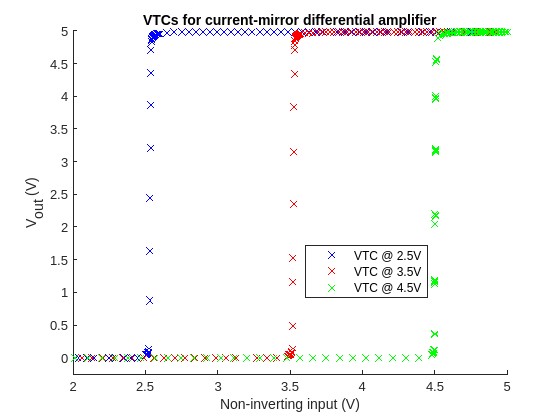

clear;
clf;
hold on;

load("Ex1_1_2-5.mat");
plot(Ch1, Vout, 'bx', 'DisplayName', 'VTC @ 2.5V');

load("Ex1_1_3-5.mat");
plot(Ch1, Vout, 'rx', 'DisplayName', 'VTC @ 3.5V');

load("Ex1_1_4-5.mat");
plot(Ch1, Vout, 'gx', 'DisplayName', 'VTC @ 4.5V');

legend("Position", [0.54385,0.29151,0.21843,0.12231]);
xlim([2 5]);
ylim([-0.25 5]);
title("VTCs for current-mirror differential amplifier")
xlabel("Non-inverting input (V)");
ylabel("V_{out} (V)");
hold off;

Compared to the VTCs from Lab 6, the amplifier now sits at 0V until we hit the non-inverting input value.

## Experiment 2

Experimental Procedure:

We used the same circuit we used in Experiment 1. In this experiment, we fixed V2 at 2.5 volts and swept V1 from 0 to 5 volts with channel 1 while measuring Vout with channel 2to get the Differential mode voltage gain. Next, we set the Vdm to 0 and swept Vout from 0 to 5 volts while measuring Iout with channel 1. Finally, we set Vdm to 2.2 by applying a voltage to V1 with channel 1 and measuring Iout with channel 2.

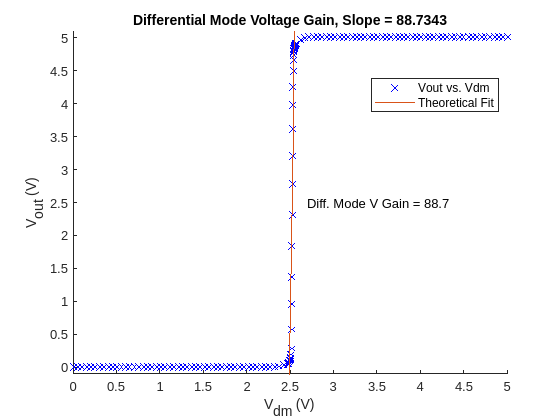

clear;
clf;

hold on;
load("Ex2_1_2-5_MI.mat");
vspace = linspace(2, 3);
vfit = 88.7343*vspace - 221.3096;

plot(Vin, Vout, "bx");
plot(vspace, vfit);

xlim([0 5]);
ylim([-0.1 5.1]);
legend("V{out} vs. V{dm}", "Theoretical Fit", "location", "best");
title("Differential Mode Voltage Gain, Slope = 88.7343");
xlabel("V_{dm} (V)");
ylabel("V_{out} (V)");
text(2.7, 2.5, "Diff. Mode V Gain = 88.7")
hold off;

Differential mode voltage gain is 88.73 Vout/Vdm.

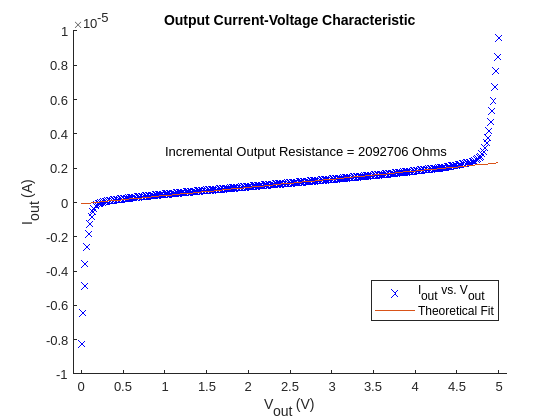

clear;
clf;

% Vdm = 0, measuring current flowing into output of amplifier
load("Ex2_2_2-5_MI.mat");
vspace = linspace(0, 5);
vfit = 4.7785e-7*vspace - 7.9196e-8;

hold on;
plot(Vout, Iout, "bx");
plot(vspace, vfit);
ylim([-1e-5 1e-5]);
xlim([-0.1 5.1]);
legend("I_{out} vs. V_{out}", "Theoretical Fit", "location", "best");
title("Output Current-Voltage Characteristic");
ylabel("I_{out} (A)");
xlabel("V_{out} (V)");
text(1, 0.3e-5, "Incremental Output Resistance = 2092706 Ohms")

The slope of the best-fit line is 4.7785e-7, so, by taking the inverse, the incremental output resistance is equal to 2092706 ohms. This is a very large incremental output resistance.

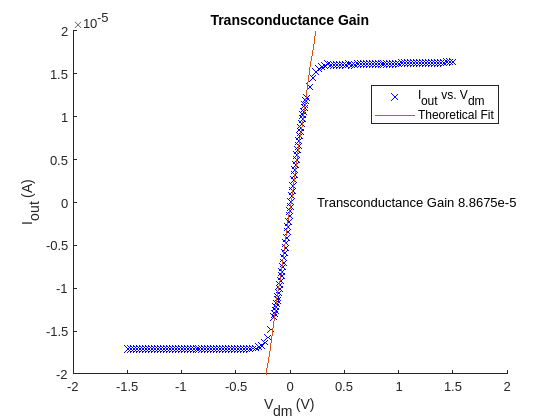

clear;
clf;
hold on;
load("Ex2_3_2-5_MI.mat");

% Vout fixed at 2.2 - sweeping Vdm over a large range where Iout
% saturates both for positive and negative values of Vdm

vspace = linspace(-1, 1);
vfit = -8.8675e-5*vspace + 7.5325e-7;
plot(Vdm, -Iout, "bx");
plot(vspace, -vfit);

xlim([-2 2]);
ylim([-0.2e-4 0.2e-4]);
legend("I_{out} vs. V_{dm}", "Theoretical Fit", "location", "best");
title("Transconductance Gain");
xlabel("V_{dm} (V)");
ylabel("I_{out} (A)");
hold off;
text(0.25, 0, "Transconductance Gain 8.8675e-5")

Our transconductance gain (the slope of the line) is 8.8675e-5 S.

Limiting value for Iout Vdm < 0 is -1.61e-5 amps and for Vdm > 0 is 1.71e-5 amps.

The differential-mode voltage gain computed by multiplying the transconductance by the resistance which yields a differential-mode voltage gain of 185 which is within an order of magnitude of the measured differential-mode voltage gain of 88. This calculated vdm gain is twice as high as the vdm gain from lab 6 which was 73.

## Experiment 3

With the circuit from experiment 1 and 2, we connected Vout to the inverting input and connected a 1nF capacitor from Vout to ground. We then used an analog discovery to apply a square wave to the non inverting input while measuring the output current.

% Define the file name of the CSV file
filename = '50mv_milo2.csv';

% Read the CSV file using readtable
data = readtable(filename);

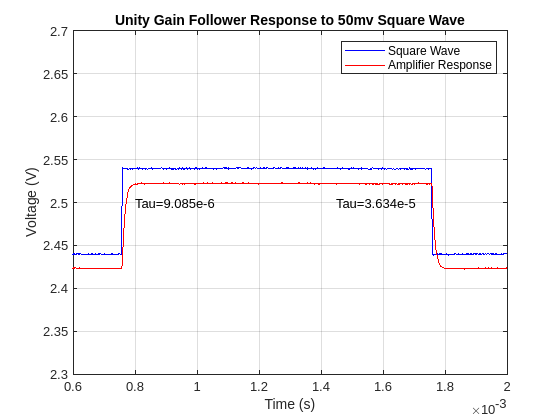


% Extract the time and voltage columns from the data
% Use the correct column names based on your CSV file
time = data.("Time_s_"); % Time column
voltage_ch1 = data.("Channel1_V_"); % Voltage column for Channel 1
voltage_ch2 = data.("Channel2_V_"); % Voltage column for Channel 2

% Plot the data
figure; % Create a new figure
plot(time, voltage_ch1, 'b-', 'DisplayName', 'Square Wave'); % Plot the voltage vs. time for Channel 1
hold on; % Hold the current plot so that we can add more data to it
plot(time, voltage_ch2, 'r-', 'DisplayName', 'Amplifier Response'); % Plot the voltage vs. time for Channel 2
 % Release the hold on the current plot
xlabel('Time (s)'); % Label the x-axis
ylabel('Voltage (V)'); % Label the y-axis
title('Unity Gain Follower Response to 50mv Square Wave'); % Add a title to the plot
legend('show'); % Show the legend
ylim([2.3 2.7])
xlim([0.6e-3 2e-3])
text(0.8e-3, 2.5, "Tau=9.085e-6");
text(1.45e-3, 2.5, "Tau=3.634e-5");
grid on; % Add a grid to the plot
hold off

The response is symmetrical when comparing the up-going and down-going step. Both of the amplifier responses resemble exponential decays towards the target voltage.

The time constant for the up-going step is 9.085e-6 seconds and the time constant for the down-going step is 3.634e-5 seconds.

The time constant computed from the measured values of the load capacitance and the differential-mode transconductance gain is 1.1277e-4. This is an order of magnitude off of our measured value. This difference is likely due to the fact that we used another lab groups circuit for measuring data in experiment where their bias gate voltage was 0.88 V and ours was 0.8 V.

clf;
% Define the file name of the CSV file
filename = '2V_milo2.csv';

% Read the CSV file using readtable
data = readtable(filename);

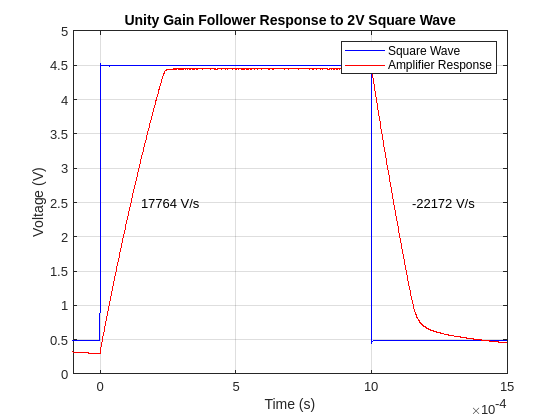


% Extract the time and voltage columns from the data
% Use the correct column names based on your CSV file
time = data.("Time_s_"); % Time column
voltage_ch1 = data.("Channel1_V_"); % Voltage column for Channel 1
voltage_ch2 = data.("Channel2_V_"); % Voltage column for Channel 2

% Plot the data
figure; % Create a new figure
plot(time, voltage_ch1, 'b-', 'DisplayName', 'Square Wave'); % Plot the voltage vs. time for Channel 1
hold on; % Hold the current plot so that we can add more data to it
plot(time, voltage_ch2, 'r-', 'DisplayName', 'Amplifier Response'); % Plot the voltage vs. time for Channel 2
 % Release the hold on the current plot
xlabel('Time (s)'); % Label the x-axis
ylabel('Voltage (V)'); % Label the y-axis
title('Unity Gain Follower Response to 2V Square Wave'); % Add a title to the plot
legend('show'); % Show the legend
xlim([-0.1e-3 1.5e-3])
text(1.5e-4, 2.5, "17764 V/s");
text(11.5e-4, 2.5, "-22172 V/s")
grid on; % Add a grid to the plot
hold off

The response is symmetrical when comparing the up-going and down-going step. Both of the amplifier responses resemble an initial linear region followed by an exponential decays towards the target voltage. 

The slew rate of the linear region in the up-going region is 17764.43 volts per second and in the down-going region is -22172.5 volts per second.

The calculated up-going slew rate from the load capicatance and limiting bias current is 16140 volts per second and the down-going slew rate is -17110 volts per second. These values are similar in the fact that the up-going slew rate is less than the down-going slew rate. Again, differences from Experiment 2 are probably due to the fact the borrowed circuit we were using to take measurements for Experiment 3 was at a slightly different bias voltage. 